FRA+EDFA/EDFA+FRA

raman Pump= 200-550

980nm Pump 60mw

Gain和NF

1550.92-193.43THz

1550.12-193.53THz

clc;
clear;

EDFA+FRA

% EDFA data
Pin_edfa = -34.550;
Pase_edfa = -37.272;
Pout_edfa = -7.532;

%raman data
Pin_raman= Pout_edfa;       % Gnet
Pase_raman = [-30.28 -27.36 -24.61 -22.21 -20.14 -18.30 -16.84 -15.73];     % power of ASE
Pout_on = [-4.24 -1.40 1.50 3.85 5.44 5.71 4.62 1.17];
Pout_off = -17.50;

% represent in W
Pin_raman=10.^(Pin_raman./10)*1e-3;
Pase_raman=10.^(Pase_raman./10)*1e-3;
Pout_on=10.^(Pout_on./10)*1e-3;
Pout_off=10.^(Pout_off./10)*1e-3;

Pin_edfa=10.^(Pin_edfa./10)*1e-3;
Pase_edfa=10.^(Pase_edfa./10)*1e-3;
Pout_edfa=10.^(Pout_edfa./10)*1e-3;

c=3e8;
h=6.62606896e-34;
wavelength=1552.912e-9;
v=c./wavelength;
Be=0.02e-9.*c./(wavelength^2);

% Raman
Gain_raman = (Pout_on - Pase_raman) ./ Pin_raman;
GAIN_raman = 10.*log10(Gain_raman)

GAIN_raman =     3.2812    6.1210    9.0214   11.3712   12.9600   13.2247   12.1209    8.6124


Geq_raman = (Pout_on)./(Pout_off);
GEQ_raman = 10.*log10(Geq_raman)

GEQ_raman =    13.2600   16.1000   19.0000   21.3500   22.9400   23.2100   22.1200   18.6700


NF_raman = 10.*log10( (Pase_raman) ./ (Gain_raman.*h*v*Be) + (1./Gain_raman));
NFeq_raman_mw = ((Pase_raman) ./ (Geq_raman.*h*v*Be) + (1./Geq_raman));
NFeq_raman = 10.*log10((Pase_raman) ./ (Geq_raman.*h*v*Be) + (1./Geq_raman))

NFeq_raman =    21.4306   21.5099   21.3595   21.4094   21.8893   23.4592   26.0092   30.5692



% EDFA
Gain_edfa = (Pout_edfa - Pase_edfa) ./ Pin_edfa;
GAIN_edfa = 10.*log10(Gain_edfa)

GAIN_edfa = 27.0134

NF_edfa_mw = ((2*Pase_edfa) ./ (Gain_edfa.*h*v*Be) + (1./Gain_edfa));
NF_edfa = 10.*log10((2*Pase_edfa) ./ (Gain_edfa.*h*v*Be) + (1./Gain_edfa))

NF_edfa = 3.6977

% total
GAIN_total1 = GAIN_raman + GAIN_edfa

GAIN_total1 =    30.2946   33.1344   36.0347   38.3846   39.9734   40.2381   39.1342   35.6258


GAIN_total = GEQ_raman + GAIN_edfa

GAIN_total =    40.2734   43.1134   46.0134   48.3634   49.9534   50.2234   49.1334   45.6834


NF_total = NF_edfa + NFeq_raman ./ GAIN_edfa 

NF_total =     4.4911    4.4940    4.4884    4.4903    4.5080    4.5662    4.6605    4.8294


FRA+EDFA

% GAIN_total_2 = [35.3881 37.3653 37.0725 32.8925 29.3080 27.2116 ];
GAIN_total_2 = [31.1884   33.8221   36.4137   39.0782   41.4730   43.7433   45.7669   47.2678];
NF_total_2 = [-2.3553   -3.1114   -3.5944   -3.8251   -4.2451   -4.0587   -3.4886   -3.1282];
GAIN_total_3 = [30.6   33.6   36.01   37.5   40.8   44.2433   45.3669   48.8];
NF_total_3 = [-2.4523   -3.1534   -3.3824   -3.9251   -4.0451   -4.2558   -3.5886   -3.2282];

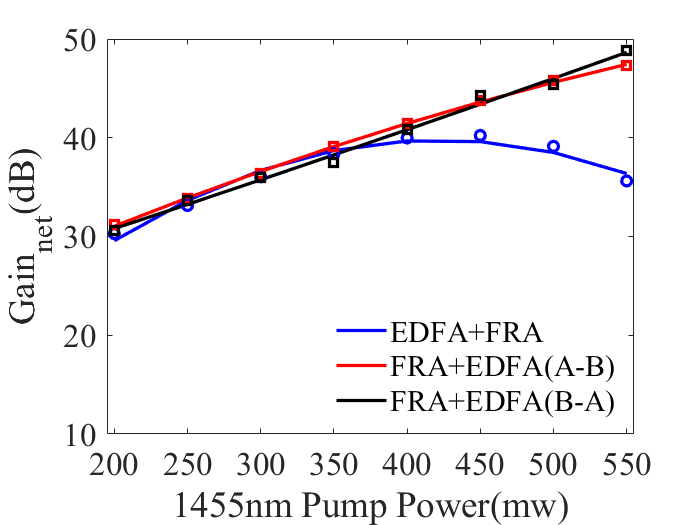

figure('Name','Gain - EDFA VS FRA+EDFA','NumberTitle','off');
box on;
hold on;
Pump = 200:50:550;

p1=polyfit(Pump,GAIN_total1,2);
y1=polyval(p1,Pump);
plot(Pump,y1,'b-','LineWidth',2);
p2=polyfit(Pump,GAIN_total_2,2);
y2=polyval(p2,Pump);
plot(Pump,y2,'r-','LineWidth',2);
p3=polyfit(Pump,GAIN_total_3,2);
y3=polyval(p3,Pump);
plot(Pump,y3,'k-','LineWidth',2);

plot(Pump,GAIN_total1,'bo','LineWidth',2);
plot(Pump,GAIN_total_2,'rs','LineWidth',2);
plot(Pump,GAIN_total_3,'ks','LineWidth',2);
hold off;

axis([195 555 10 50]);
xlabel('1455nm Pump Power(mw)','FontSize',20,'Fontname', 'Times New Roman');
ylabel('Gain_n_e_t(dB)','FontSize',20,'Fontname', 'Times New Roman');
set(gca,'FontSize',20,'Fontname', 'Times New Roman');
set(gca,'xtick',[200 250 300 350 400 450 500 550]);
legend({'EDFA+FRA','FRA+EDFA(A-B)','FRA+EDFA(B-A)'},'Location','southeast','NumColumns',1)
legend('boxoff')

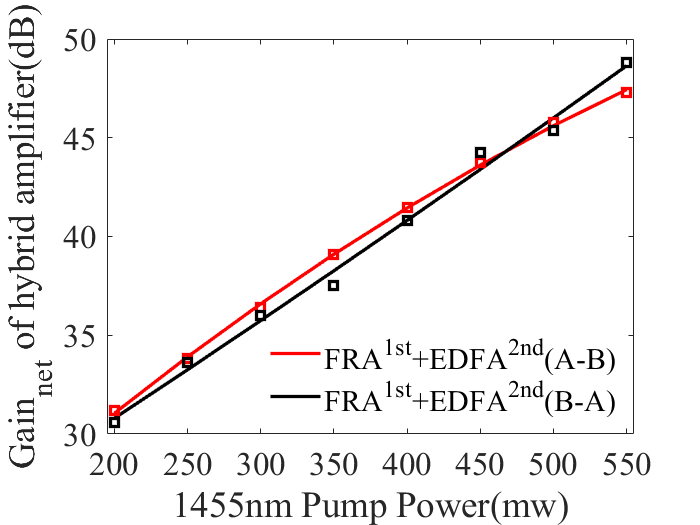

figure('Name','Gain - EDFA VS FRA+EDFA','NumberTitle','off');
box on;
hold on;
Pump = 200:50:550;

% p1=polyfit(Pump,GAIN_total1,2);
% y1=polyval(p1,Pump);
% plot(Pump,y1,'b-','LineWidth',2);
p2=polyfit(Pump,GAIN_total_2,2);
y2=polyval(p2,Pump);
plot(Pump,y2,'r-','LineWidth',2);
p3=polyfit(Pump,GAIN_total_3,2);
y3=polyval(p3,Pump);
plot(Pump,y3,'k-','LineWidth',2);

% plot(Pump,GAIN_total1,'bo','LineWidth',2);
plot(Pump,GAIN_total_2,'rs','LineWidth',2);
plot(Pump,GAIN_total_3,'ks','LineWidth',2);
hold off;

axis([195 555 30 50]);
xlabel('1455nm Pump Power(mw)','FontSize',20,'Fontname', 'Times New Roman');
ylabel('Gain_n_e_t of hybrid amplifier(dB)','FontSize',20,'Fontname', 'Times New Roman');
set(gca,'FontSize',20,'Fontname', 'Times New Roman');
set(gca,'xtick',[200 250 300 350 400 450 500 550]);
legend({'FRA^1^s^t+EDFA^2^n^d(A-B)','FRA^1^s^t+EDFA^2^n^d(B-A)'},'Location','southeast','NumColumns',1)
legend('boxoff')

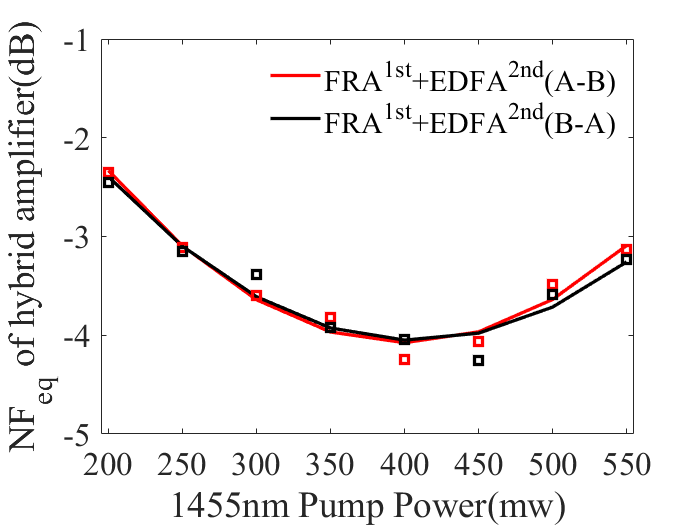

figure('Name','NF - EDFA VS FRA+EDFA','NumberTitle','off');
box on;
hold on;
Pump = 200:50:550;

% p1=polyfit(Pump,NF_total,2);
% y1=polyval(p1,Pump);
% plot(Pump,y1,'b-','LineWidth',2);
p2=polyfit(Pump,NF_total_2,2);
y2=polyval(p2,Pump);
plot(Pump,y2,'r-','LineWidth',2); 
p3=polyfit(Pump,NF_total_3,2);
y3=polyval(p3,Pump);
plot(Pump,y3,'k-','LineWidth',2);

% plot(Pump,NF_total,'bo','LineWidth',2);
plot(Pump,NF_total_2,'rs','LineWidth',2);
plot(Pump,NF_total_3,'ks','LineWidth',2);
hold off;

axis([195 555 -5 -1]);
xlabel('1455nm Pump Power(mw)','FontSize',20,'Fontname', 'Times New Roman');
ylabel('NF_e_q of hybrid amplifier(dB)','FontSize',20,'Fontname', 'Times New Roman');
set(gca,'FontSize',20,'Fontname', 'Times New Roman');
set(gca,'xtick',[200 250 300 350 400 450 500 550]);
legend({'FRA^1^s^t+EDFA^2^n^d(A-B)','FRA^1^s^t+EDFA^2^n^d(B-A)'},'Location','northeast','NumColumns',1)
legend('boxoff')

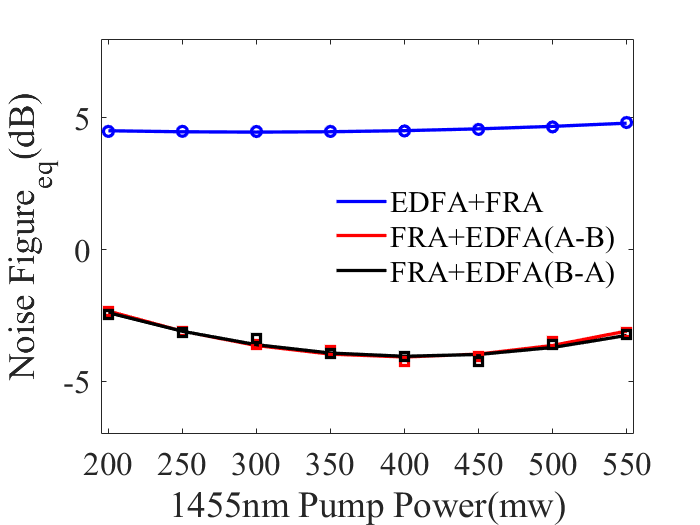

figure('Name','NF - EDFA VS FRA+EDFA','NumberTitle','off');
box on;
hold on;
Pump = 200:50:550;

p1=polyfit(Pump,NF_total,2);
y1=polyval(p1,Pump);
plot(Pump,y1,'b-','LineWidth',2);
p2=polyfit(Pump,NF_total_2,2);
y2=polyval(p2,Pump);
plot(Pump,y2,'r-','LineWidth',2); 
p3=polyfit(Pump,NF_total_3,2);
y3=polyval(p3,Pump);
plot(Pump,y3,'k-','LineWidth',2);

plot(Pump,NF_total,'bo','LineWidth',2);
plot(Pump,NF_total_2,'rs','LineWidth',2);
plot(Pump,NF_total_3,'ks','LineWidth',2);
hold off;

axis([195 555 -7 8]);
xlabel('1455nm Pump Power(mw)','FontSize',20,'Fontname', 'Times New Roman');
ylabel('Noise Figure_e_q(dB)','FontSize',20,'Fontname', 'Times New Roman');
set(gca,'FontSize',20,'Fontname', 'Times New Roman');
set(gca,'xtick',[200 250 300 350 400 450 500 550]);
legend({'EDFA+FRA','FRA+EDFA(A-B)','FRA+EDFA(B-A)'},'Location','east','NumColumns',1)
legend('boxoff')

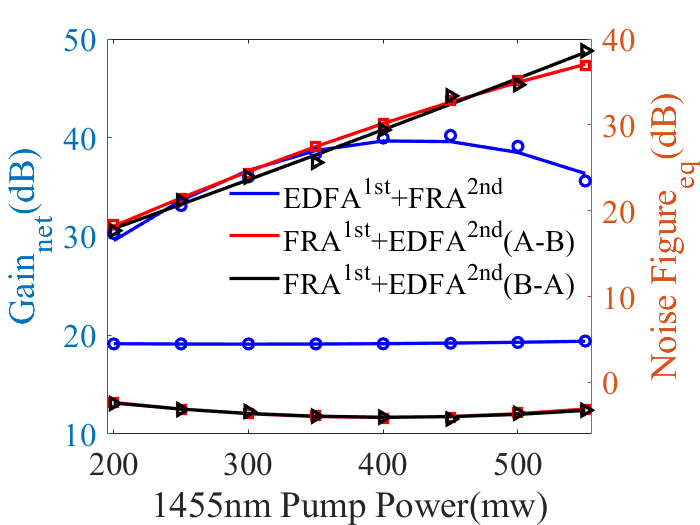

figure('Name','Gain - EDFA VS FRA+EDFA','NumberTitle','off');
box on;
hold on;
Pump = 200:50:550;

yyaxis left;
p1=polyfit(Pump,GAIN_total1,2);
y1=polyval(p1,Pump);
plot(Pump,y1,'b-','LineWidth',2);
p2=polyfit(Pump,GAIN_total_2,2);
y2=polyval(p2,Pump);
plot(Pump,y2,'r-','LineWidth',2);
p3=polyfit(Pump,GAIN_total_3,2);
y3=polyval(p3,Pump);
plot(Pump,y3,'k-','LineWidth',2);

yyaxis right;
p1=polyfit(Pump,NF_total,2);
y1=polyval(p1,Pump);
c11 = plot(Pump,y1,'b-','LineWidth',2);
p2=polyfit(Pump,NF_total_2,2);
y2=polyval(p2,Pump);
c12 = plot(Pump,y2,'r-','LineWidth',2); 
p3=polyfit(Pump,NF_total_3,2);
y3=polyval(p3,Pump);
c13 = plot(Pump,y3,'k-','LineWidth',2);

yyaxis left;
plot(Pump,GAIN_total1,'bo','LineWidth',2);
plot(Pump,GAIN_total_2,'rs','LineWidth',2);
plot(Pump,GAIN_total_3,'k>','LineWidth',2);

yyaxis right;
plot(Pump,NF_total,'bo','LineWidth',2);
plot(Pump,NF_total_2,'rs','LineWidth',2);
plot(Pump,NF_total_3,'k>','LineWidth',2);
hold off;

yyaxis left;
axis([195 555 10 50]);
xlabel('1455nm Pump Power(mw)','FontSize',20,'Fontname', 'Times New Roman');
ylabel('Gain_n_e_t(dB)','FontSize',20,'Fontname', 'Times New Roman');
yyaxis right;
axis([195 555 -6 40]);
ylabel('Noise Figure_e_q(dB)','FontSize',20,'Fontname', 'Times New Roman');
set(gca,'FontSize',20,'Fontname', 'Times New Roman');
% set(gca,'xtick',[200 250 300 350 400 450 500 550]);
legend({'EDFA^1^s^t+FRA^2^n^d','FRA^1^s^t+EDFA^2^n^d(A-B)','FRA^1^s^t+EDFA^2^n^d(B-A)'},'Location','east','NumColumns',1)
legend('boxoff')